# **Generación de Números Aleatorios**

`Autor: Dr. Abdelmalik Moujahid`

# **Método de composición**

El **método de la composición** es una técnica utilizada para generar variables aleatorias con una distribución específica combinando variables aleatorias de una o más distribuciones conocidas. El objetivo es generar una variable aleatoria con una distribución de probabilidad deseada a partir de distribuciones más simples y conocidas.

La idea principal del método de la composición **es expresar la función de densidad de probabilidad (PDF) de la variable aleatoria deseada** como una **combinación ponderada de PDFs de otras variables aleatorias más simples.** Luego, se utiliza un esquema de selección para decidir de cuál de estas distribuciones más simples se debe tomar la muestra.

El procedimiento general del método de la composición puede describirse en los siguientes pasos:

- **Expresión de la PDF deseada: **Expresar la función de densidad de probabilidad deseada, $f\left(x\right)$, como una combinación ponderada de PDFs de otras distribuciones más simples. Es decir, 


$$f\left(x\right)=\sum_i \;\omega_i {\;g}_i \left(x\right)$$


            donde $\omega_i \;$son los pesos (probabilidades) y ${\;g}_i \left(x\right)$ son las PDFs de las distribuciones      

            conocidas.

- **Generación de Variables Aleatorias**: Generar variables aleatorias $X_i$ de las distribuciones conocidas ${\;g}_i \left(x\right)$.

- **Esquema de Selección**: Utilizar un esquema de selección para elegir una de las distribuciones ${\;g}_i \left(x\right)$ con probabilidad proporcional a su peso $\omega_i$. Esto se puede hacer, por ejemplo, utilizando la técnica de la función de distribución acumulativa inversa.

- **Generación de la Variable Aleatoria Deseada**: Generar la variable aleatoria deseada $X$ a partir de la variable aleatoria seleccionada $X_i$�.

# Método de la Composición:

Se desea generar valores de variables aleatorias que siguen la siguiente distribución de probabilidad denominada distribución triangular.

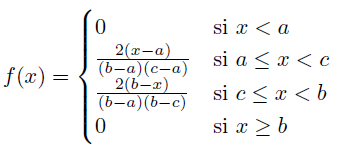

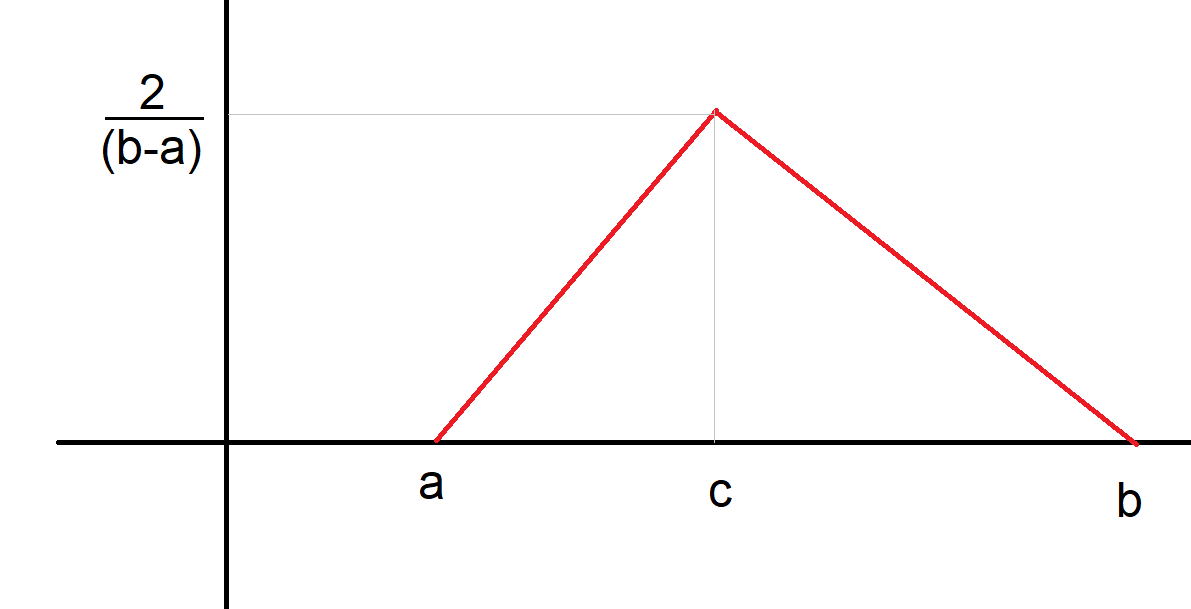

#### Función Densidad de Probabilidad (PDF)

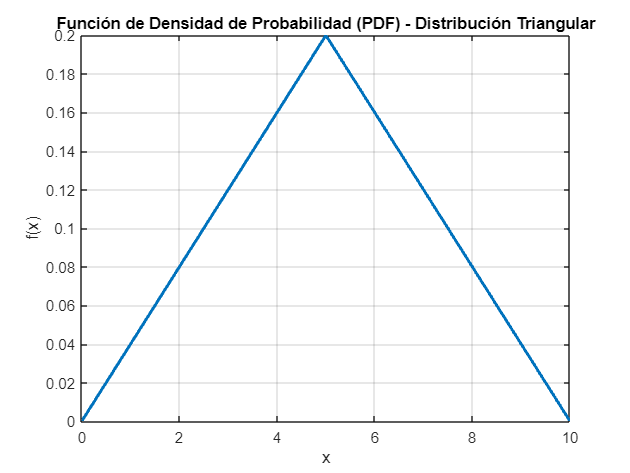

% Parámetros de la distribución triangular
a = 0;
b = 10;
c = 5;

% Definir la función de densidad de probabilidad (PDF)
PDF = @(x) (x < a) .* 0 + ((a <= x) & (x < c)) .* (2 * (x - a) / ((b - a) * (c - a))) + ...
    ((c <= x) & (x < b)) .* (2 * (b - x) / ((b - a) * (b - c))) + (x >= b) .* 0;

% Crear un rango de valores x para evaluar la PDF
x_values = linspace(a, b, 1000);

% Evaluar la PDF en los valores x
y_values = arrayfun(PDF, x_values);

% Plotear la PDF
plot(x_values, y_values, 'LineWidth', 2);
title('Función de Densidad de Probabilidad (PDF) - Distribución Triangular');
xlabel('x');
ylabel('f(x)');
grid on;

syms a b c x
f1 = @(x) 2*(x-a)/((b-a)*(c-a));
f2 = @(x) 2*(b-x)/((b-a)*(b-c));

% verificar que la integral de la PDF en el intervalo [a,b] es igual a 1.
int(f1,x,a,c)+int(f2,x,c,b)

$$ans = \frac{a-c}{a-b}-\frac{b-c}{a-b}$$

#### Función de Distribución Acumulativa (CDF)

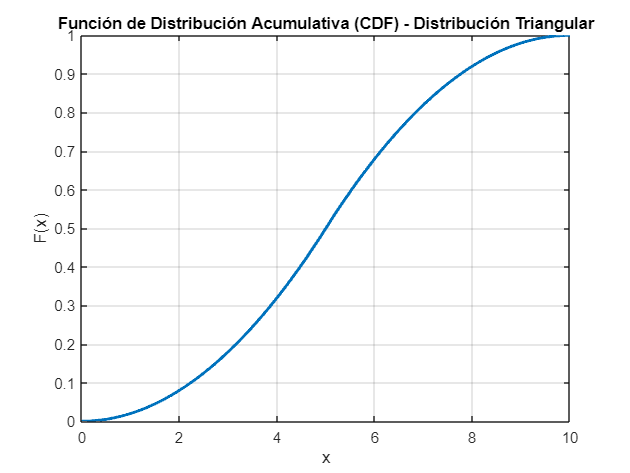

% Parámetros de la distribución triangular
a = 0;
b = 10;
c = 5;

% Definir la función de distribución acumulativa (CDF)
CDF = @(x) (x < a) .* 0 + ((a <= x) & (x < c)) .* ((x-a).^2 / ((b-a)*(c-a))) + ...
    ((c <= x) & (x < b)) .* (1 - ((b-x).^2 / ((b-a)*(b-c)))) + (x >= b) .* 1;

% Crear un rango de valores x para evaluar la CDF
x_values = linspace(a, b, 1000);

% Evaluar la CDF en los valores x
y_values = arrayfun(CDF, x_values);

% Plotear la CDF
plot(x_values, y_values, 'LineWidth', 2);
title('Función de Distribución Acumulativa (CDF) - Distribución Triangular');
xlabel('x');
ylabel('F(x)');
grid on;

#### Método de la Composición

Ahora, podemos derivar la función de densidad de probabilidad (PDF) de $X$ utilizando el método de la composición. 

Definimos $F_X \left(x\right)$ como la **función de distribución acumulativa (CDF) **de $X$:


$$F_X \left(x\right)=P\left(X\le x\right)$$


Podemos expresar la CDF como:

$\left.F_X \left(x\right)=P\left(a+\sqrt{U_1 \left(b-a\right)\left(c-a\right)}\right)\le x\right)$ si $U_1 \le \frac{c-a}{b-a}$

y

$\left.F_X \left(x\right)=P\left(b-\sqrt{\left(1-U_1 \right)\left(b-a\right)\left(b-c\right)}\right)\le x\right)$ si $U_1 \ge \;\frac{c-a}{b-a}$

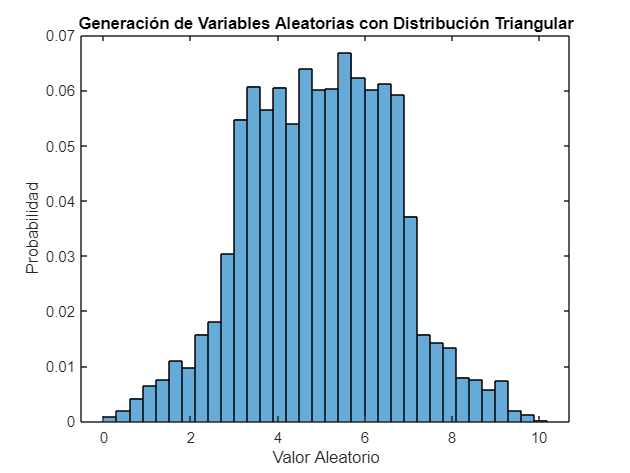


clear all

% Número de muestras a generar
num_samples = 5000;

% Generar variables aleatorias uniformes en [0, 1]
U1 = rand(1, num_samples);
U2 = rand(1, num_samples);

% Parámetros de la distribución triangular
a = 0;
b = 10;
c = 5;

% Método de la composición para generar variables aleatorias triangulares
X = zeros(1, num_samples);
for i = 1:num_samples
    if U1(i) <= (c-a)/(b-a)
        X(i) = a + sqrt(U2(i) * (b-a) * (c-a));
    else
        X(i) = b - sqrt((1-U2(i)) * (b-a) * (b-c));
    end
end

% Visualizar los resultados
histogram(X, 'Normalization', 'probability');
title('Generación de Variables Aleatorias con Distribución Triangular');
xlabel('Valor Aleatorio');
ylabel('Probabilidad');